% SHAPC-Mean and SHAPC-Var Comparison
clear;

setup;
tests = ["full", "full_1000", "first_last", "first_last_1000"];
dataset = 'cifar100';

if dataset == "cifar100"
    num_sessions = 10;
    tests = ["full_1000" "full_2000" "first_last_1000" "first_last_2000"];
else
    num_sessions = 5;
end
if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end

shapc_path = sprintf("%s_shapc_data.mat", dataset);

if isfile(shapc_path)
    sh_nm = fieldnames(load(shapc_path));
    shapc_data = load(shapc_path).(string(sh_nm));
else
    shapc_data = struct();
end

% Load SHAPC values

all_shapcs = zeros(length(algs), length(tests));
all_times = zeros(length(algs), length(tests));

for t=1:length(tests)
    for a=1:length(algs)
        alg = algs(a);
        save_path = sprintf("%s/%s/shapc_vals_%s.mat", alg, dataset, tests(t));
        if isfile(save_path)
            shapc_struct = load(save_path);
           
            % Load SHAPC values all
            shapc_avgs = [];
            for i=1:num_sessions-1
                if t > 2
                    test_loop = num_sessions-1;
                else
                    test_loop = i:num_sessions-1;
                end

                for j=test_loop
                    pair_str = 'sc' + string(i-1) + string(j);
                    shapcs = [];
                    sample_list = fieldnames(shapc_struct.(pair_str));
                    for k=1:length(sample_list)
                        shapcs = [shapcs; shapc_struct.(pair_str).(sample_list{k})];
                    end
                    shapc_avgs = [shapc_avgs; mean(shapcs)];
            
                end
            end
            
            % Note the shapc is represented as percentage
            %disp("From averaging all tasks together:")
            shapc_mean_perc = mean(shapc_avgs);
            shapc_mean = mean(shapc_avgs) / 100;
        else
            shapc_mean_perc = NaN;
            shapc_mean = NaN;
        end
        test_shapc_str = tests(t) + string("_shapc");
        shapc_data.(alg).(test_shapc_str) = shapc_mean_perc;
        all_shapcs(a,t) = shapc_data.(alg).(test_shapc_str);
        
        test_time_str = tests(t) + string("_time");
        if isfield(shapc_data.(alg), test_time_str)
            all_times(a,t) = shapc_data.(alg).(test_time_str);
        else
            all_times(a,t) = NaN;
        end
    end
    save(shapc_path, "shapc_data")
end

% Compare Methods
rows = algs;
if dataset == "cifar100"
    columns = ["Full"  "Full 2000" "First/Last" "First/Last 2000"];
else
    columns = ["Full"  "Full 1000" "First/Last" "First/Last 1000"];
end

shapc_table_comp = array2table(all_shapcs,'VariableNames', columns, 'RowNames', rows)

shapc_table_comp = 9×4 table
               Full     Full 2000    First/Last    First/Last 2000
              ______    _________    __________    _______________

    iTAML     28.196     28.213         27.26          27.483     
    RPSnet       NaN     31.073        30.739             NaN     
    foster    32.914     32.956        28.709          28.785     
    memo      31.399     31.333        31.252          30.992     
    der       42.528     42.704        41.429           41.64     
    icarl     28.016     28.011        27.218          27.316     
    dsal      44.344     43.992         43.72          43.498     
    tagfex       NaN     42.876        40.625          40.717     
    xder   

time_table_comp = array2table(all_times, 'VariableNames', columns, 'RowNames', rows)

time_table_comp = 9×4 table
               Full     Full 2000    First/Last    First/Last 2000
              ______    _________    __________    _______________

    iTAML     35.285     6.9942        4.6611          0.96139    
    RPSnet       NaN      22.14        38.185              NaN    
    foster    9.1128     1.6289        2.9536          0.54694    
    memo      14.588     2.7364        5.0711          0.85972    
    der        31.98     6.0283        10.866           2.3489    
    icarl     6.4567     1.1167        2.0808             0.32    
    dsal      20.282     3.8119        6.9719           1.3114    
    tagfex       NaN     17.232        34.667           7.8061    
    xder    

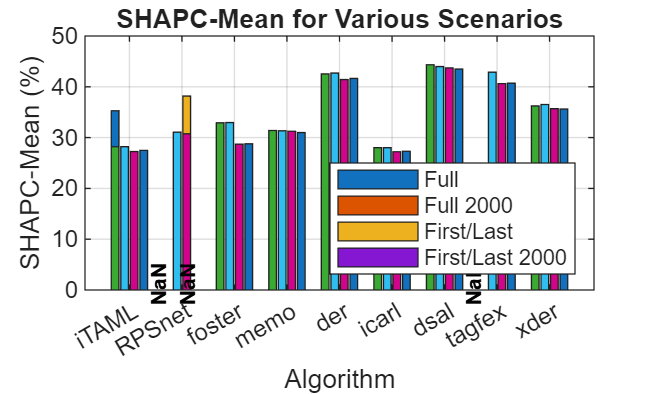

% Create Graph
%{
Y = [full_shapcs'; first_last_shapcs'; 
    full_1000_shapcs'; first_last_1000_shapcs'];
bar(columns, Y)
legend(algs, 'Location', 'southeast')
%}

%%{
%Y = [];
%for i=1:5
%    Y = [Y; [full_shapcs(i) full_1000_shapcs(i) first_last_shapcs(i) first_last_1000_shapcs(i)]];
%end
x = columns;
shapc_bar = bar(algs, all_shapcs);

%%{
hold on;
% Loop through each series (each column in your data)
for i = 1:size(all_shapcs, 2)
    % Find NaN indices for this specific series
    nanIdx = isnan(all_shapcs(:, i));
    
    if any(nanIdx)
        % Get the actual X-coordinates for this specific bar series
        % hBar(i).XEndPoints contains the precise horizontal centers
        xCoords = shapc_bar(i).XEndPoints(nanIdx);
        yCoords = zeros(size(xCoords));
        
        % Place the text
        text(xCoords+0.07, yCoords+1.25, 'NaN', ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'bottom', ...
            'Rotation', 90, ...
            'Color', 'black', ...
            'FontWeight', 'bold', ...
            'FontSize', 8);
    end
end
%}

legend(x, 'Location', 'southeast')
title('SHAPC-Mean for Various Scenarios');
xlabel('Algorithm');
ylabel('SHAPC-Mean (%)');
grid on
hold off;

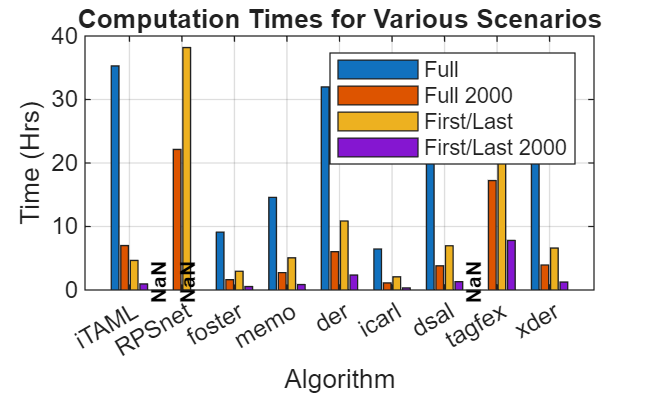


%Y = [];
%for i=1:5
%    Y = [Y; [full_times(i) full_1000_times(i) first_last_times(i) first_last_1000_times(i)]];
%end
time_bar = bar(algs, all_times);
hold on;
% Loop through each series (each column in your data)
for i = 1:size(all_shapcs, 2)
    % Find NaN indices for this specific series
    nanIdx = isnan(all_shapcs(:, i));
    
    if any(nanIdx)
        % Get the actual X-coordinates for this specific bar series
        % hBar(i).XEndPoints contains the precise horizontal centers
        xCoords = time_bar(i).XEndPoints(nanIdx);
        yCoords = zeros(size(xCoords));
        
        % Place the text
        text(xCoords+0.07, yCoords+1.25, 'NaN', ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'bottom', ...
            'Rotation', 90, ...
            'Color', 'black', ...
            'FontWeight', 'bold', ...
            'FontSize', 8);
    end
end
%}

legend(x);%, 'Location', 'southeast')
title('Computation Times for Various Scenarios');
xlabel('Algorithm');
ylabel('Time (Hrs)');
grid on

% Standard Deviation
std_devs = std(all_shapcs')';
std_dev_table = table(std_devs, 'RowNames', rows)

std_dev_table = 9×1 table
              std_devs
              ________

    iTAML     0.48947 
    RPSnet        NaN 
    foster     2.4182 
    memo      0.17829 
    der       0.63447 
    icarl     0.43263 
    dsal      0.36447 
    tagfex        NaN 
    xder      0.43293 


%{
%Create Hatch Pattern
Y_hatch = Y;
Y_hatch(:,2) = NaN;
Y_hatch(:,4) = NaN;
bar(algs, Y)
%legend(columns, 'Location', 'southeast')

hold on;
b_hatch = bar(algs, Y_hatch);

% 5. Apply the hatch pattern
b_hatch.Pattern = 'crosshatch'; % Apply a pattern
b_hatch.FaceColor = 'none'; % Makes the original bar's color visible
b_hatch.EdgeColor = 'black'; % Optional: change hatch line color

hold off; % Release the hold

%}